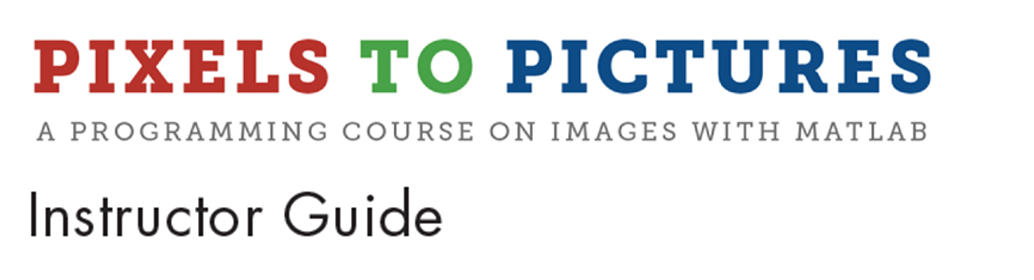

# Module 16: Creating an Animated GIF

**Prerequisite Domain Knowledge:** Loops, reading images, showing images

**Expected Completion Time: **50 minutes

## Creating an Animated GIF

*Expected Duration: 50 minutes*

### Learning Objectives

- Using the ‘for’ loop construct, series of images can be viewed as a video/animation

### Materials

- MATLAB®

### **Steps**

The other name for a video is motion picture which, literally, means pictures in motion. Videos are a series of pictures projected on a screen in rapid succession where all the objects in each picture only slightly change in position. This produces the optical effect of a continuous picture (or video) in which the objects seem to be in motion.

Tell the students that they will be using a series of images and displaying them on screen one picture at a time to create a video.

Open the basic script that displays all the 12 frames of a stick figure by typing the following command in MATLAB Command Window:

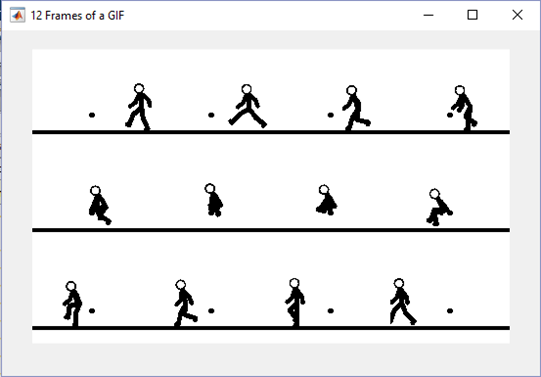

Ask the students to open the following script:

 
open 'FlipBookBasic.mlx'

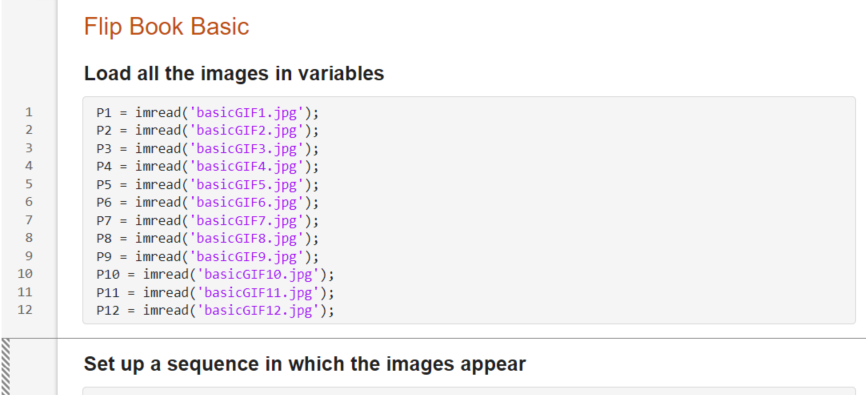

The first step to creating a GIF is to load all these images. These images are named as ‘basicGIF1.jpg’, ‘basicGIF2.jpg’ … ‘basicGIF12.jpg’. This step has already been completed using the `imread` function. 

Run the script and observe the variables `P1, P2, …, P12` in the workspace.

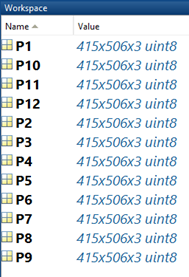

The second step to creating a motion picture is to determine what order each of these image files are displayed on screen. For this example, we will use all the 12 images in order. 

To define the order in which the images are displayed, we will use something called cell arrays. Tell the students that cell arrays work in the same way a vector or a matrix works. Here are the primary differences:

- A vector or matrix contains single numeric values as elements of the vector or matrix, but cell arrays can contain an entire image (which is a matrix by itself) as one of its elements. In fact, a single cell array can contain elements of different types of data, e.g., characters, scalar values, matrices etc. In the following command, `A` is a cell array containing a scalar value, a matrix and a character array:

              So basically it is like a container that contains different contents inside it.

- Cell arrays use curly braces ‘{ }’ instead of parenthesis ‘( )’.

The purpose of this task is to set up the order of displaying images. It is defined as a cell array containing the variables `P1 – P12` in workspace in the corresponding desired sequence in which the images should be displayed one after the other.

The next step should be to display these images one at a time using the `imshow` function. Ask the students how they would do it. They will probably suggest typing the `imshow` command 12 times like below:

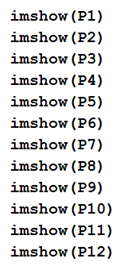

This will certainly work, but this is not the most efficient way of doing a repetitive task. When we know we have to execute a command several times, we can instead use a for-loop.

In this example, since there are 12 images, the for-loop will run 12 times. We can explicitly set the for-loop by specifying that for-loop runs 12 times:

Or, we can use the `numel` function on the variable movement. This function gives the number of elements in a variable as its output. 

                 

For the “do something ” portion inside the loop, this is where the `imshow` function will go. 

The image we want `imshow` to show needs to change every iteration. We can do this by extracting the variable name from the movement cell array. 

Extracting from cell array is the same concept as extracting elements from vectors – indexing. 

But for vectors and matrices we use parenthesis () to index, for cell arrays we use curly braces {} to index. 

So in the first iteration in the code below (`k `= 1), we show `movement{1} `→`P1`, for the second iteration (`k `= 2), we show `movement{2} `→`P2`, and so on. 

Run the script. Note that the images are shown very quickly. We can optionally add a `pause` command, which pauses MATLAB for 0.1 seconds before showing the next image. This stops the script from changing the images too quickly before our eyes can register the change. We can change the pause amount as needed:

Students can now create a GIF file from the images that can be viewed outside MATLAB. So they can take the file home and watch it in their computer.  MATLAB is not needed to view the file. This can be done by using the `writeGifFrame` function as follows:

The inputs of the function are as follows:

- Filename - (char array) Desired name of the GIF file

- Image - (RGB image) 3-D matrix that represents the current frame of GIF image

- Index - (scalar) The index of the current frame being written

- Delay_time -(scalar) Delay time for change of frames

When the script is run, a GIF file with the name ‘MyGIF.gif’ will be created and will be visible in the Current Folder:

 

The completed script should look as follows:

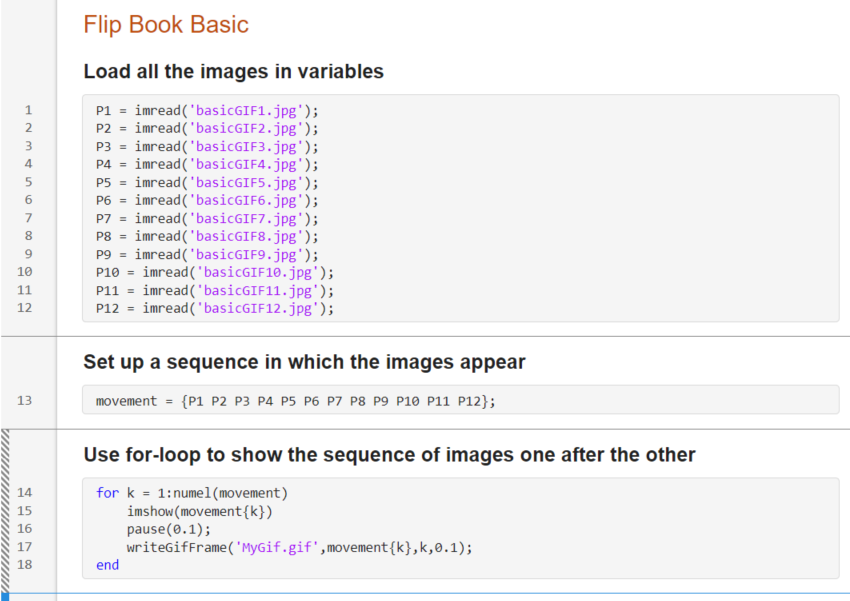

After you have given the students time to create their own GIF file, ask:

- *What are the limitations of the video you just created?  *

-     There are only 12 images in the video, so it is very short. To make a longer video you need to load and display a lot of images, which can make the code very long.

-     In the above example, there is a pause of 0.1 seconds after every video is displayed. This creates a ‘lag’ and the video does not seem to run smoothly. 

Tell students that in the original film projector, there are 24 frames (or 24 images) displayed in 1 second.  (That means there is a pause of 1/24 ≈ 0.04 seconds).  The present digital camera in our phones has the capability of recording a video at 30 and 60 frames per second.  This means that when you record a video with your phone, you are capturing 30 or 60 images in one second and putting them one after the other.

Let the students know that they can use their own images taken from their smart device instead of the GIF images, put them in a loop and increase the pause/delay time to see them as a video. 

© COPYRIGHT 2024 by The MathWorks®, Inc.